## Creating "clean" 1000Hz signal using Matlab

Setting up the parameters

% some parameters and preps
fs = 10000;             % sampling frequency
T = 10;                 % duration in seconds
n = randn(fs*T, 1);     % some random vector (white noise)

Identifying the length of the vector

% identify the length of the vector
len_n_samples = length(n);      % in samples
len_n_s = length(n) / fs;       % in time

Calculate the frequency vector

% calculate the frequency vector
T0 = length(n) / fs;            % duration of the signal in seconds
delta_f = 1 / T0;               % frequency resolution

Get the positive frequencies first

% get the positive frequencies first
f_pos = 0:delta_f:fs/2;         % positive frequencies up to fs/2 (Nyquist)
f_neg = -fs/2+delta_f:delta_f:-delta_f;  % negative frequencies from -fs/2 to 0

Now we calculate the spectrum of our signal

% Now we calculate the spectrum of our signal and plot it on a meaningful axis!
Y = fft(n);                     % Compute the FFT of the signal

Take only positive frequencies (single-sided spectrum)

% Take only positive frequencies (single-sided spectrum)
Y_pos = Y(1:floor(length(Y)/2) + 1);  % Only positive part of the spectrum

Plot the magnitude of the spectrum (in dB)

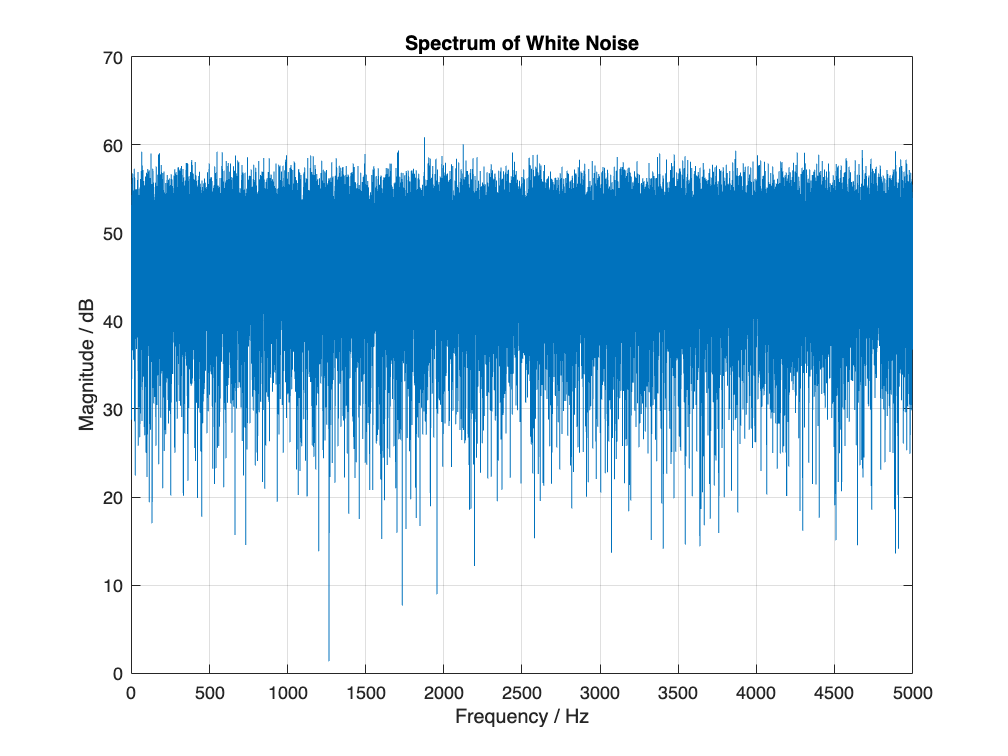

% Plot the magnitude of the spectrum (in dB)
figure;
plot(f_pos, 20*log10(abs(Y_pos)));
xlabel('Frequency / Hz');
ylabel('Magnitude / dB');
title('Spectrum of White Noise');
grid on;

Generate and plot a sinusoidal signal

% Generate and plot a sinusoidal signal
[x_values, y_values] = generate_sinusoid(1, 1000, 0, fs, 0.5);

Call the make_spectrum function

[Y_clean, freq_clean] = make_spectrum(y_values, fs);

TEST !!!!!

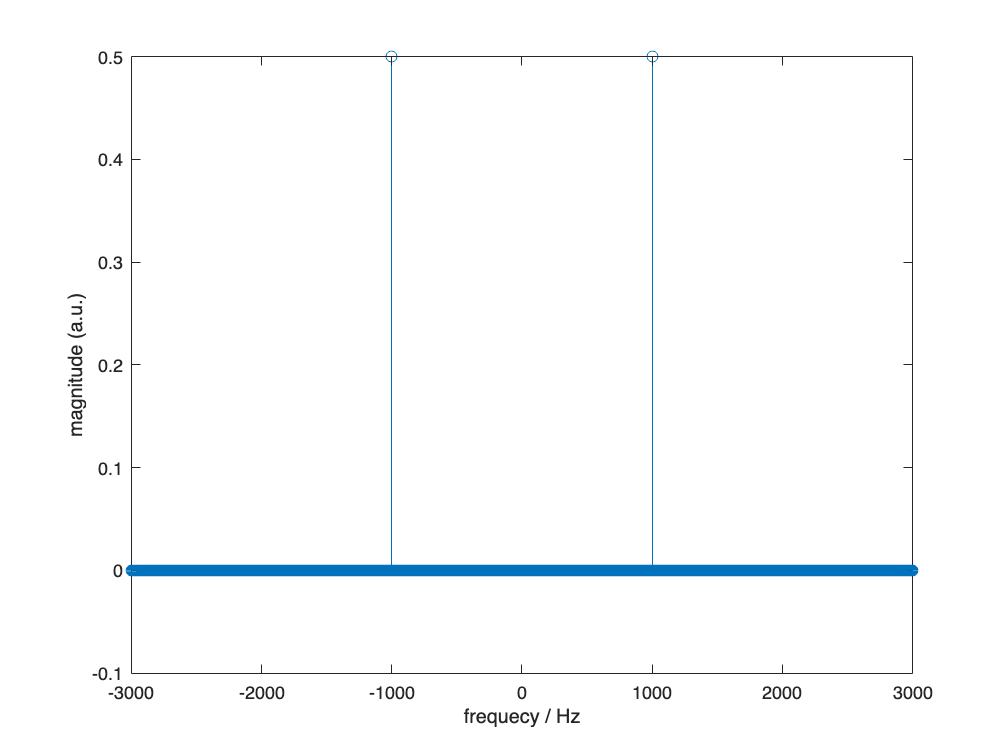

stem(freq_clean, abs(Y_clean))
xlim([-fs/2 fs/2])
xlabel('frequecy / Hz')
ylabel('magnitude (a.u.)')

xlim([-3000 3000])
ylim([-0.100 0.500])

Plot the spectrum for the sinusoidal signal

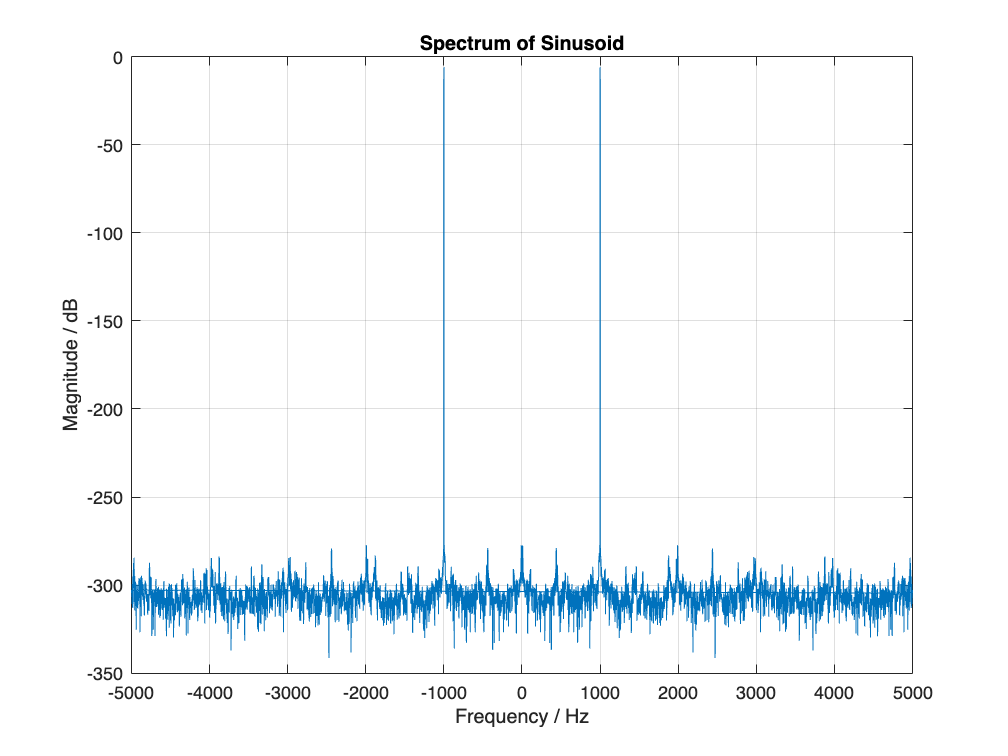

% Plot the spectrum for the sinusoidal signal
figure;
plot(freq_clean, 20*log10(abs(Y_clean)));
xlim([-fs/2 fs/2]);
xlabel('Frequency / Hz');
ylabel('Magnitude / dB');
title('Spectrum of Sinusoid');
grid on;

Function to generate a sinusoid

% Function to generate a sinusoid
function [time_vector, signal] = generate_sinusoid(a, f, phi, fs, T_s)
    % Generates a sinusoidal signal
    time_vector = 0:1/fs:T_s-1/fs;  % Time vector (duration T_s)
    signal = a * cos(2 * pi * f * time_vector + phi);  % Sinusoidal signal
end

## Analyzing recorded signal

Read your own .wav file

% Read your own .wav file
[signal, fs] = audioread('myRecording.wav');

If the signal is stereo, convert it to mono by averaging the two channels

% If the signal is stereo, convert it to mono by averaging the two channels
if size(signal, 2) == 2
    signal = mean(signal, 2);
end

Identify the length of the signal

% % Identify the length of the signal
% len_signal_samples = length(signal);     % in samples
% len_signal_s = len_signal_samples / fs;  % in seconds

Calculate the frequency vector

% % Calculate the frequency vector
% T0 = len_signal_samples / fs;           % Duration of the signal in seconds
% delta_f = 1 / T0;                       % Frequency resolution

Call the make_spectrum function

% Call the make_spectrum function
[Y_record, freq_record] = make_spectrum(signal(end-24000+1:end), fs); % 

Plotting the stem function

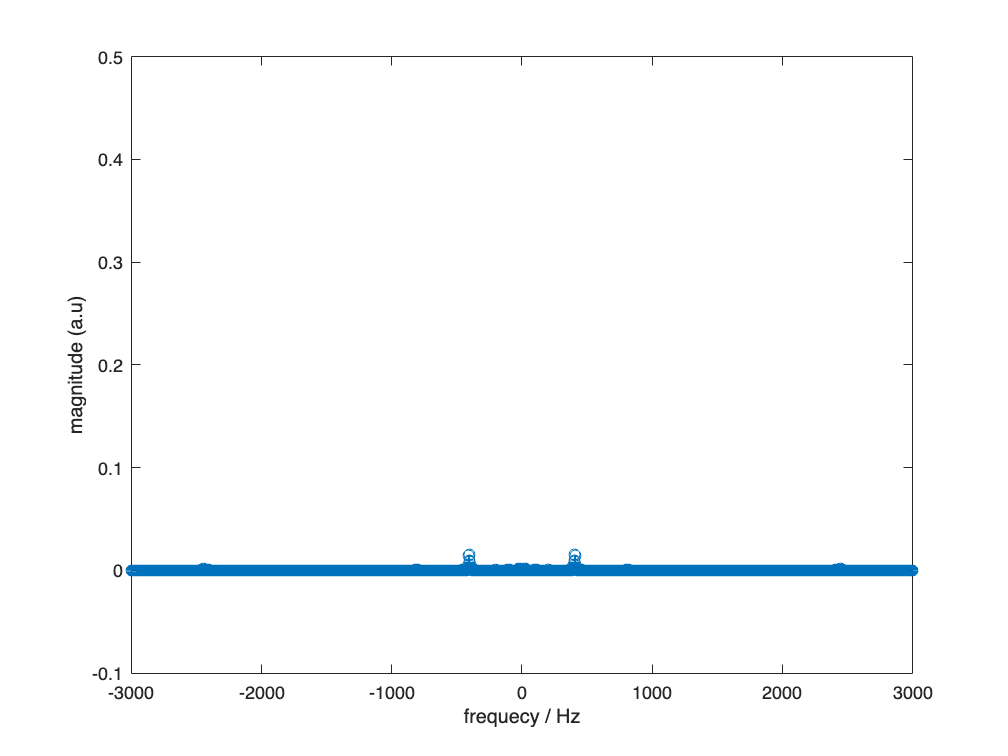

stem(freq_record, abs(Y_record))
xlim([-fs/2 fs/2])
xlabel('frequecy / Hz')
ylabel('magnitude (a.u)')

xlim([-3000 3000])
ylim([-0.100 0.500])

Plot the magnitude spectrum of your recording

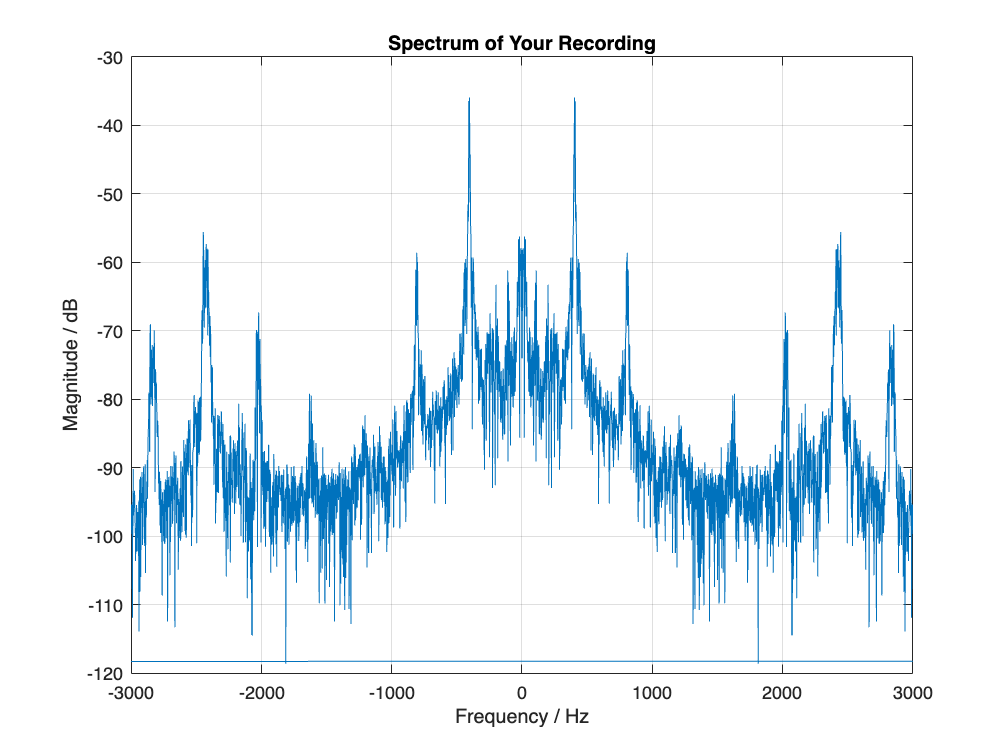

% Plot the magnitude spectrum of your recording
% NOTE: Vi ser et plot med harmoniske svingninger, men dette
% giver også god mening eftersom vores stemme opfører sig harmonisk
figure;
plot(freq_record, 20*log10(abs(Y_record)));
xlim([-fs/2 fs/2]);
xlabel('Frequency / Hz');
ylabel('Magnitude / dB'); % det passer med at y-aksen er logaritmisk
title('Spectrum of Your Recording');
grid on;

% Limit the x-axis to match your original plot
xlim([-3000 3000]);

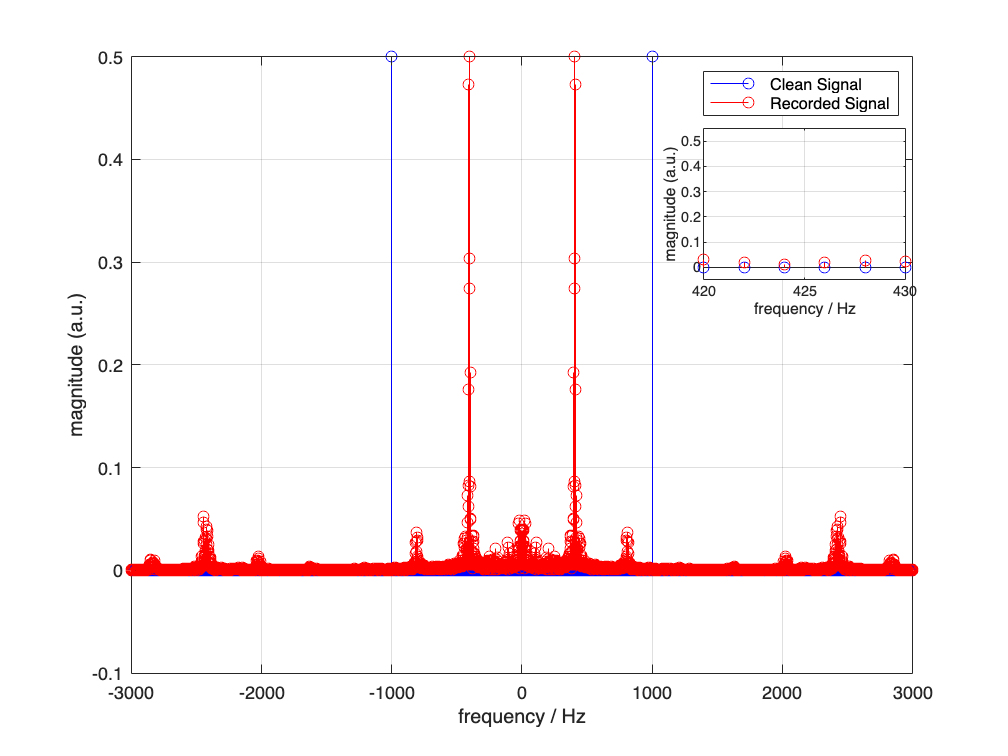

% ... [Your previous code up to the combined stem plots]

% Find the maximum magnitude of Y_clean and Y_record
max_Y_clean = max(abs(Y_clean));
max_Y_record = max(abs(Y_record));

% Check for zero maximum magnitude to avoid division by zero
if max_Y_clean == 0
    error('The clean signal has a maximum magnitude of zero.');
end
if max_Y_record == 0
    error('The recorded signal has a maximum magnitude of zero.');
end

% Scale Y_clean and Y_record so that their maximum magnitude is 0.5
Y_clean_scaled = (Y_clean / max_Y_clean) * 0.5;
Y_record_scaled = (Y_record / max_Y_record) * 0.5;

% Combine the two stem plots with scaled magnitudes
figure;

% Main axes
hMainAxes = axes;
stem(hMainAxes, freq_clean, abs(Y_clean_scaled), 'b', 'DisplayName', 'Clean Signal');
hold(hMainAxes, 'on');
stem(hMainAxes, freq_record, abs(Y_record_scaled), 'r', 'DisplayName', 'Recorded Signal');
xlabel('frequency / Hz');
ylabel('magnitude (a.u.)');
xlim(hMainAxes, [-3000 3000]);
ylim(hMainAxes, [-0.100 0.500]);
legend();
grid on;
hold(hMainAxes, 'off');

% Create inset axes
axesPosition = [0.698 0.63 0.20 0.20]; % Adjust as needed
hInsetAxes = axes('Position', axesPosition);

% Plot the zoomed-in data in the inset axes
stem(hInsetAxes, freq_clean, abs(Y_clean_scaled), 'b');
hold(hInsetAxes, 'on');
stem(hInsetAxes, freq_record, abs(Y_record_scaled), 'r');
xlabel(hInsetAxes, 'frequency / Hz');
ylabel(hInsetAxes, 'magnitude (a.u.)');
xlim(hInsetAxes, [420 430]);      % Adjust as needed
ylim(hInsetAxes, [-0.05 0.55]);    % Adjust as needed
set(hInsetAxes, 'FontSize', 8);
grid(hInsetAxes, 'on');
box(hInsetAxes, 'on');
hold(hInsetAxes, 'off');

% Ensure tick labels are displayed
set(hInsetAxes, 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
set(hInsetAxes, 'YTickMode', 'auto', 'YTickLabelMode', 'auto');

Combined plots of stem plots

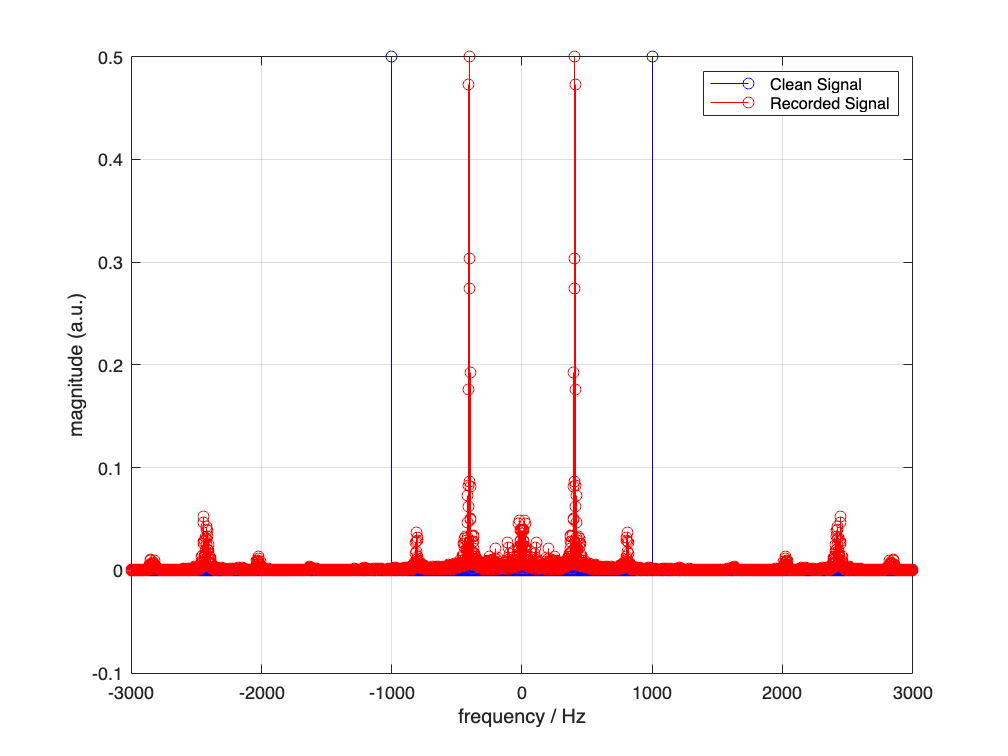

% Find the maximum magnitude of Y_clean and Y_record
max_Y_clean = max(abs(Y_clean));
max_Y_record = max(abs(Y_record));

% Check for zero maximum magnitude to avoid division by zero
if max_Y_clean == 0
    error('The clean signal has a maximum magnitude of zero.');
end
if max_Y_record == 0
    error('The recorded signal has a maximum magnitude of zero.');
end

% Scale Y_clean and Y_record so that their maximum magnitude is 0.5
Y_clean_scaled = (Y_clean / max_Y_clean) * 0.5;
Y_record_scaled = (Y_record / max_Y_record) * 0.5;

% Combine the two stem plots with scaled magnitudes
figure;
stem(freq_clean, abs(Y_clean_scaled), 'b', 'DisplayName', 'Clean Signal');
hold on;
stem(freq_record, abs(Y_record_scaled), 'r', 'DisplayName', 'Recorded Signal');
xlabel('frequency / Hz');
ylabel('magnitude (a.u.)');
xlim([-3000 3000]);
ylim([-0.100 0.500]);
legend();
grid on;
hold off;

Combined plots of the spectra

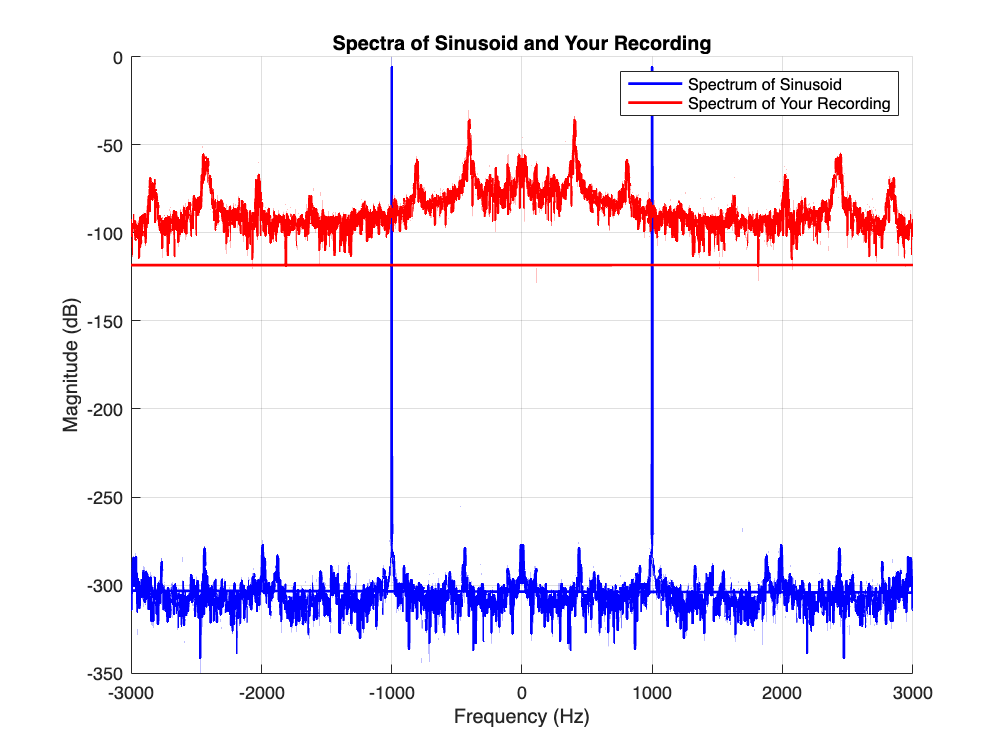

figure;
hold on;

% Plot the spectrum of the sinusoidal signal
plot(freq_clean, 20*log10(abs(Y_clean)), 'b', 'LineWidth', 1.5, 'DisplayName', 'Spectrum of Sinusoid');

% Plot the spectrum of your recording
plot(freq_record, 20*log10(abs(Y_record)), 'r', 'LineWidth', 1.5, 'DisplayName', 'Spectrum of Your Recording');

% Set the x-axis limits
xlim([-3000 3000]);

% Label the axes and add a title
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Spectra of Sinusoid and Your Recording');

% Add a grid
grid on;

% Add a legend to distinguish between the two plots
legend('show');

hold off;